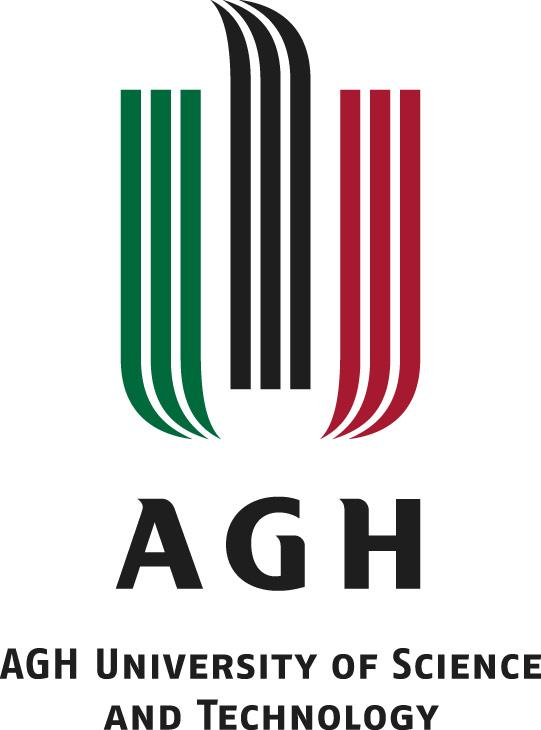

# MECHATRONIC DESIGN

# Lab 1: Introduction to Finite Difference (FD) method

## Mikołaj Suchoń

## Task 1:


clear
%% Material & discretization (from lab)
E   = 70e9;      % Young's modulus [Pa] (aluminum)
rho = 2700;      % density [kg/m^3]
c   = sqrt(E/rho); % wave speed [m/s]
fprintf('Aluminum wave speed c = %.1f m/s\n', c);

Aluminum wave speed c = 5091.8 m/s



dx = 1e-3;       % spatial step 1 mm
dt = 0.12e-6;    % time step 0.12 microsecond
r = c*dt/dx;
fprintf('CFL r = %.4f\n', r);

CFL r = 0.6110


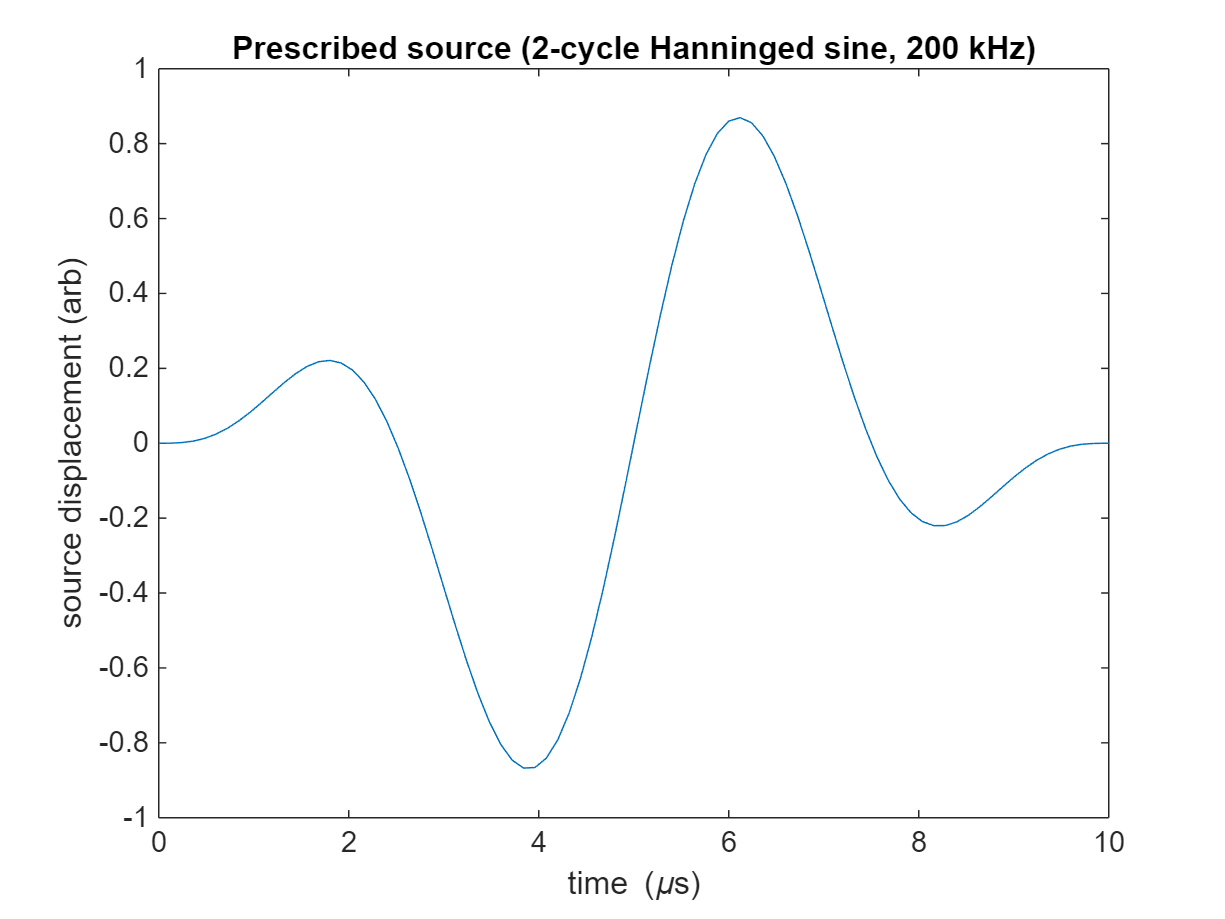


%% Domain & time
L = 0.5;                   % rod length [m] (600 mm)
x = 0:dx:L;
Nx = numel(x);

tmax = 150e-6;             % total simulation time (s)
nt = ceil(tmax/dt);
time = (0:nt-1)*dt;

%% Source (200 kHz, 2 cycles, Hanning envelope)
f0 = 200e3; ncycles = 2;
Tcycle = 1/f0;
Tsrc = ncycles * Tcycle;
t_src = (0:nt-1)*dt;                % time vector for source (longer than needed, ok)
src_envelope = zeros(size(t_src));
idx_src = (t_src >= 0) & (t_src <= Tsrc);
src_envelope(idx_src) = 0.5*(1 - cos(2*pi*t_src(idx_src)/Tsrc)); % Hanning over [0,Tsrc]
src_signal = sin(2*pi*f0*t_src) .* src_envelope;

% quick plot of the source to confirm shape
figure('Name','Input source'); plot(t_src*1e6, src_signal); xlabel('time (\mus)'); ylabel('source displacement (arb)'); title('Prescribed source (2-cycle Hanninged sine, 200 kHz)');
xlim([0 10])

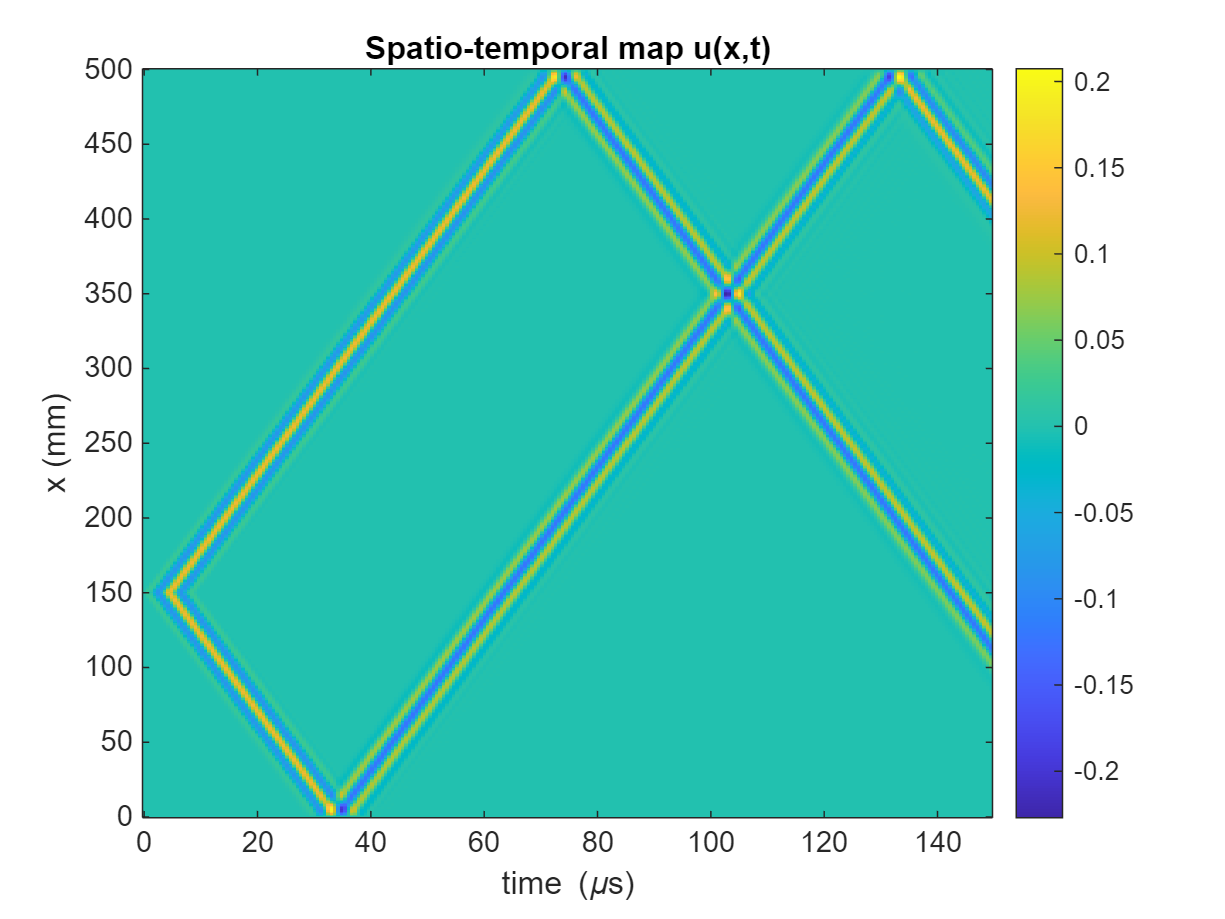



%% Source location
xsrc = 0.150;                         % 150 mm
[~, isrc] = min(abs(x - xsrc));

%% Initialize fields (time levels)
u_prev = zeros(Nx,1);   % u^{n-1}
u_curr = zeros(Nx,1);   % u^{n}
u_next = zeros(Nx,1);   % u^{n+1}

% Set initial source displacement at t=0 (u_curr) and t=-dt (u_prev) for smooth start
u_curr(isrc) = src_signal(1);
% For u_prev, assume source before t=0 is 0 (or equal to src at negative time if desired)
u_prev(isrc) = 0;

%% Measurement points (to compare traces with source)
x_meas1 = 0.050; [~, i_meas1] = min(abs(x - x_meas1)); % 50 mm
x_meas2 = 0.300; [~, i_meas2] = min(abs(x - x_meas2)); % 300 mm
trace1 = zeros(nt,1);
trace2 = zeros(nt,1);

%% Precompute
r2 = (c*dt/dx)^2;

%% Time-stepping (explicit central-difference)
% We'll store a spatio-temporal matrix at regular snapshot intervals for plotting
Ksnap = max(1, floor(nt/250));
nSnaps = ceil(nt / Ksnap);
stamps = zeros(Nx, nSnaps);
snapIdx = 1;


%------------------------------------------------------------------------------%
%--- 1) Precompute discrete acceleration of the 2-cycle Hann signal
%------------------------------------------------------------------------------%
src_acc = zeros(size(src_signal));
% central second difference for 2 ≤ n ≤ nt-1
src_acc(2:end-1) = ( ...
     src_signal(3:end) ...
   - 2*src_signal(2:end-1) ...
   + src_signal(1:end-2) ...
) / dt^2;
% set edges to zero (no injection at n=1 or n=nt)
src_acc(1)   = 0;
src_acc(end) = 0;

% Main loop
for n = 1:nt
  % time-stepping interior
  for i = 2:Nx-1
    u_next(i) = 2*u_curr(i) - u_prev(i) ...
               + r2*(u_curr(i+1) - 2*u_curr(i) + u_curr(i-1));
  end

  % ----------- ADD: exact acceleration forcing at source -------------
  u_next(isrc) = u_next(isrc) + src_acc(n)*dt^2;

  % Dirichlet at ends
  u_next(1)  = 0;
  u_next(Nx) = 0;

  % record
  trace1(n) = u_next(i_meas1);
  trace2(n) = u_next(i_meas2);
  if mod(n,Ksnap)==0
    stamps(:,snapIdx) = u_next; 
    snapIdx = snapIdx + 1;
  end

  % shift
  u_prev = u_curr;
  u_curr = u_next;
end

%% Plot spatio-temporal map and traces and compare to source (shifted)
figure('Name','Task1: Spatio-temporal & traces','Units','normalized','Position',[0.05 0.05 0.9 0.8]);

figure
time_snaps = (0:(size(stamps,2)-1))*Ksnap*dt;
imagesc(time_snaps*1e6, x*1e3, stamps); axis xy;
xlabel('time (\mus)'); ylabel('x (mm)');
title('Spatio-temporal map u(x,t)'); colorbar;

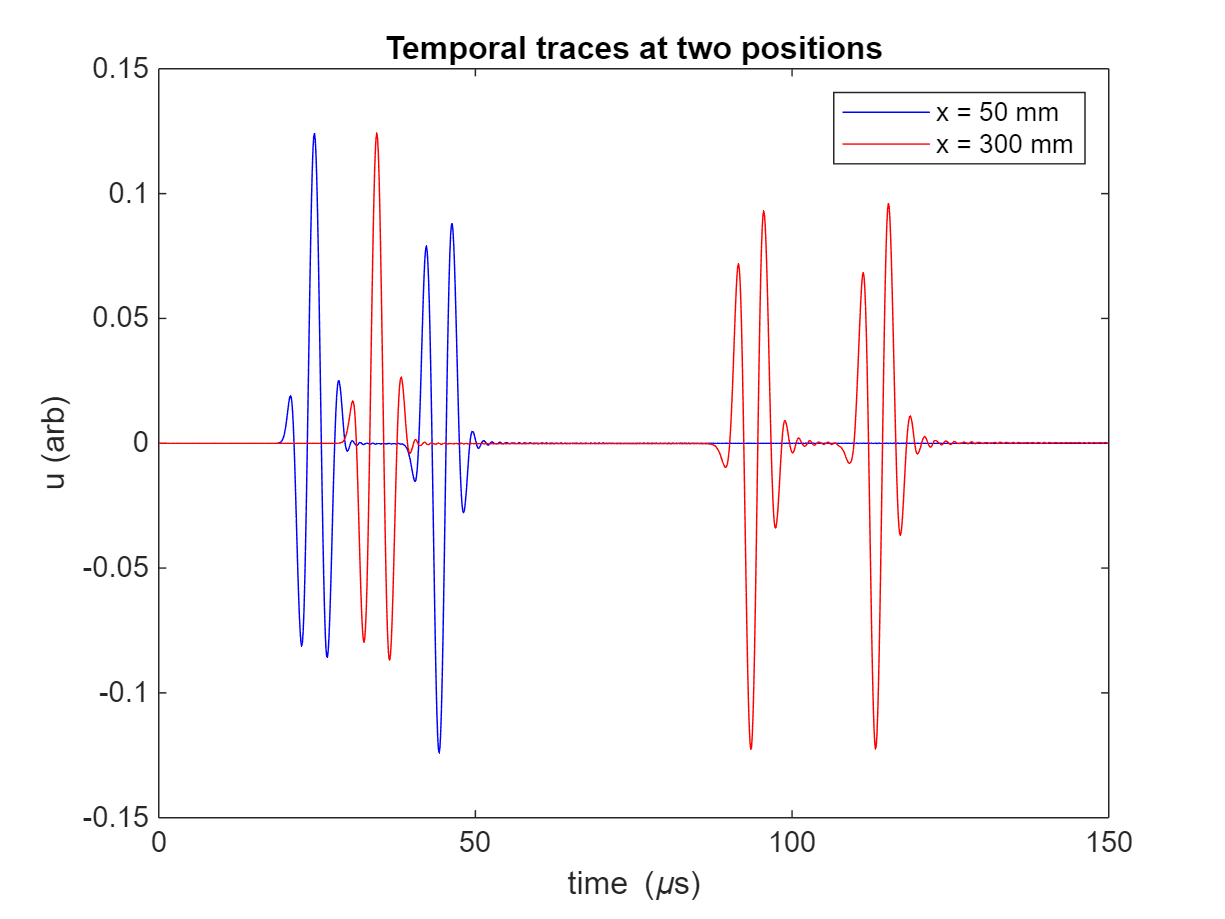


figure
plot(time*1e6, trace1, 'b'); hold on;
plot(time*1e6, trace2, 'r'); xlabel('time (\mus)'); ylabel('u (arb)');
legend(sprintf('x = %.0f mm', x_meas1*1e3), sprintf('x = %.0f mm', x_meas2*1e3));
title('Temporal traces at two positions');


%% Estimate wave speed from arrival times
% Find first strong peak in each trace (use absolute)
minPeakHeight1 = 0.25 * max(abs(trace1));
minPeakHeight2 = 0.25 * max(abs(trace2));
[pks1, locs1] = findpeaks(abs(trace1), 'MinPeakHeight', max(minPeakHeight1,eps), 'MinPeakDistance', 3);
[pks2, locs2] = findpeaks(abs(trace2), 'MinPeakHeight', max(minPeakHeight2,eps), 'MinPeakDistance', 3);
if ~isempty(locs1) && ~isempty(locs2)
    tA = locs1(1)*dt;
    tB = locs2(1)*dt;
    est_c = abs(x(i_meas2)-x(i_meas1))/(tB - tA);
    fprintf('Estimated wave speed (Task1) = %.1f m/s (theoretical c = %.1f m/s)\n', est_c, c);
else
    fprintf('Could not reliably pick arrival peaks for speed estimation.\n');
end

Estimated wave speed (Task1) = 25406.5 m/s (theoretical c = 5091.8 m/s)


## Task 2:

Aluminum wave speed c = 5091.8 m/s
CFL = 0.6110
Source at x=250.0 mm, y=250.0 mm (i=251, j=251)


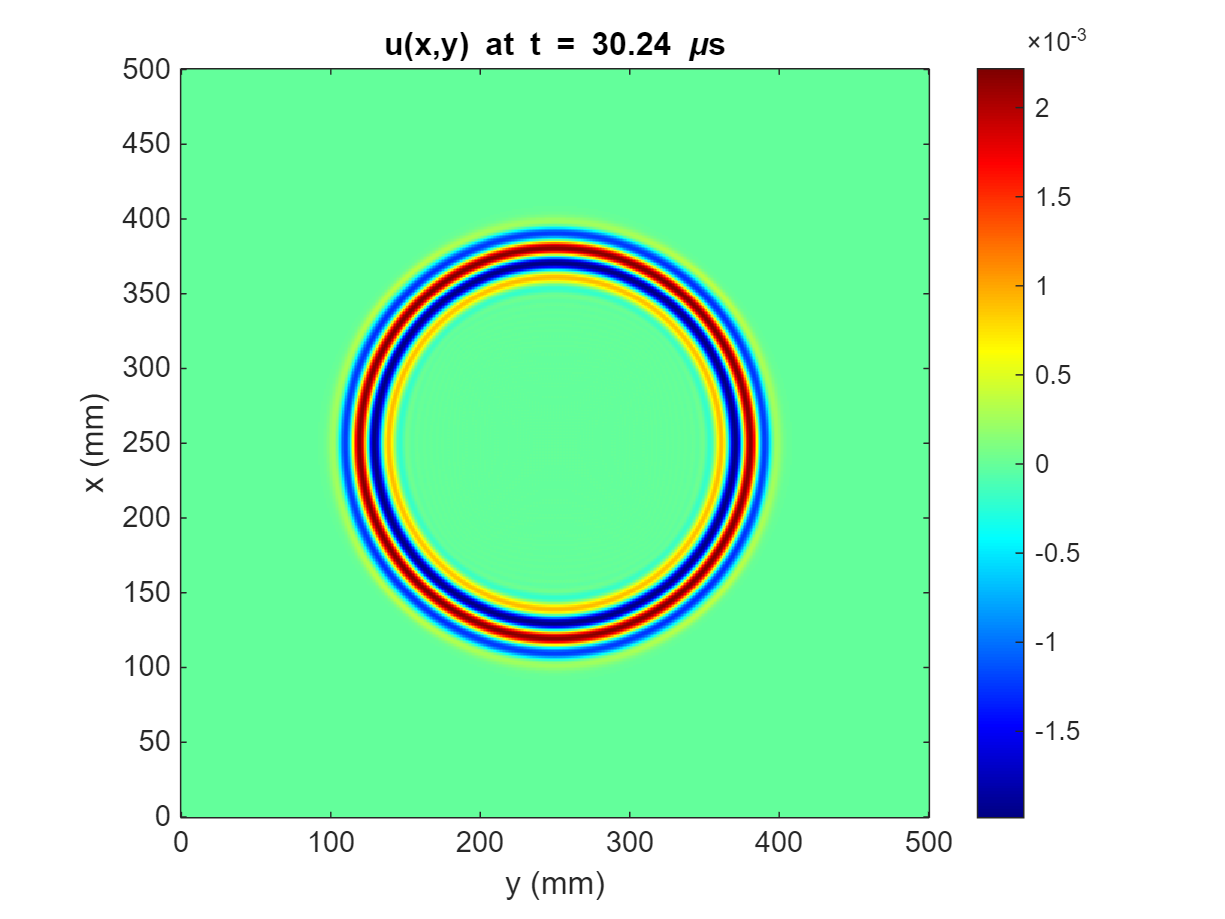

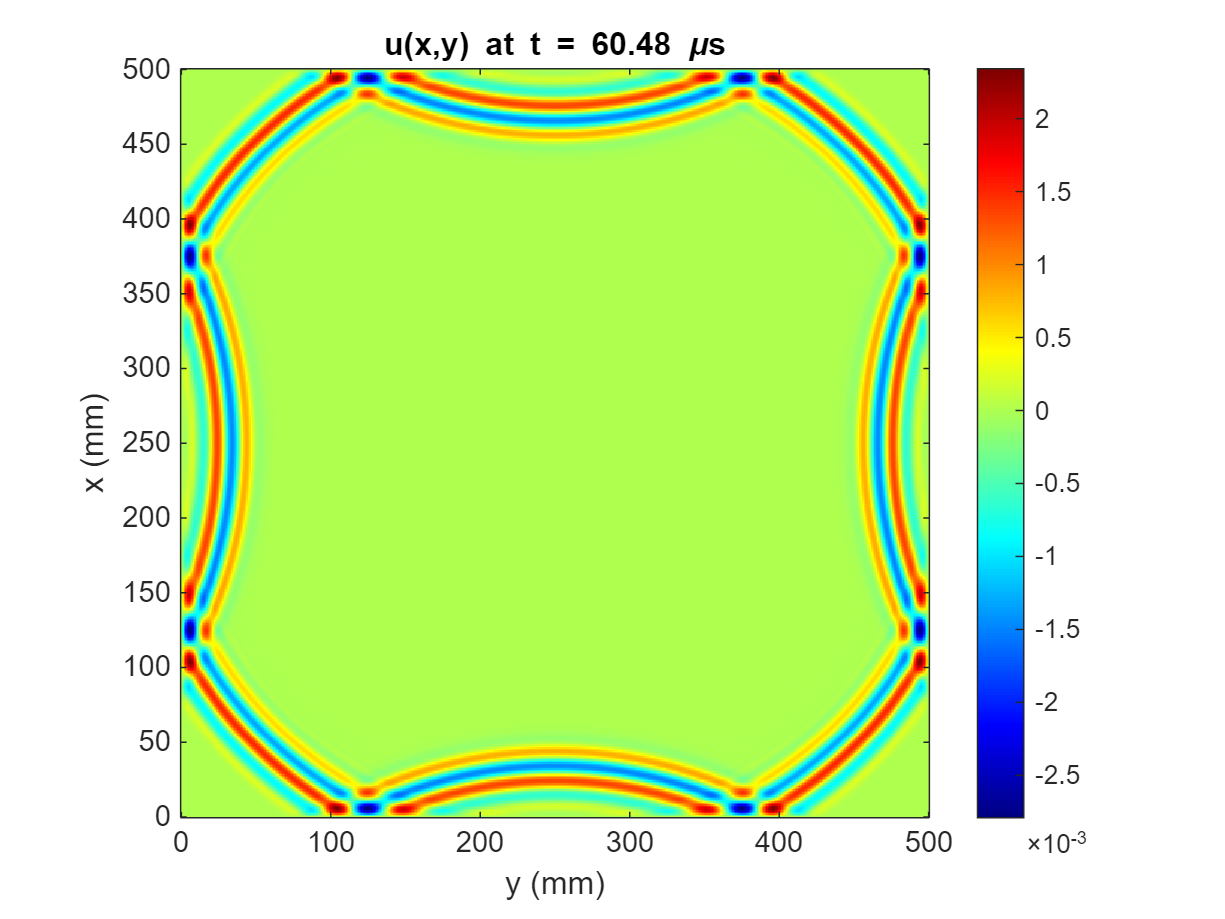

% 2D acoustic wave on an aluminum plate
clear
sim2DF(0.25,0.25)

Aluminum wave speed c = 5091.8 m/s
CFL = 0.6110
Source at x=200.0 mm, y=100.0 mm (i=201, j=101)


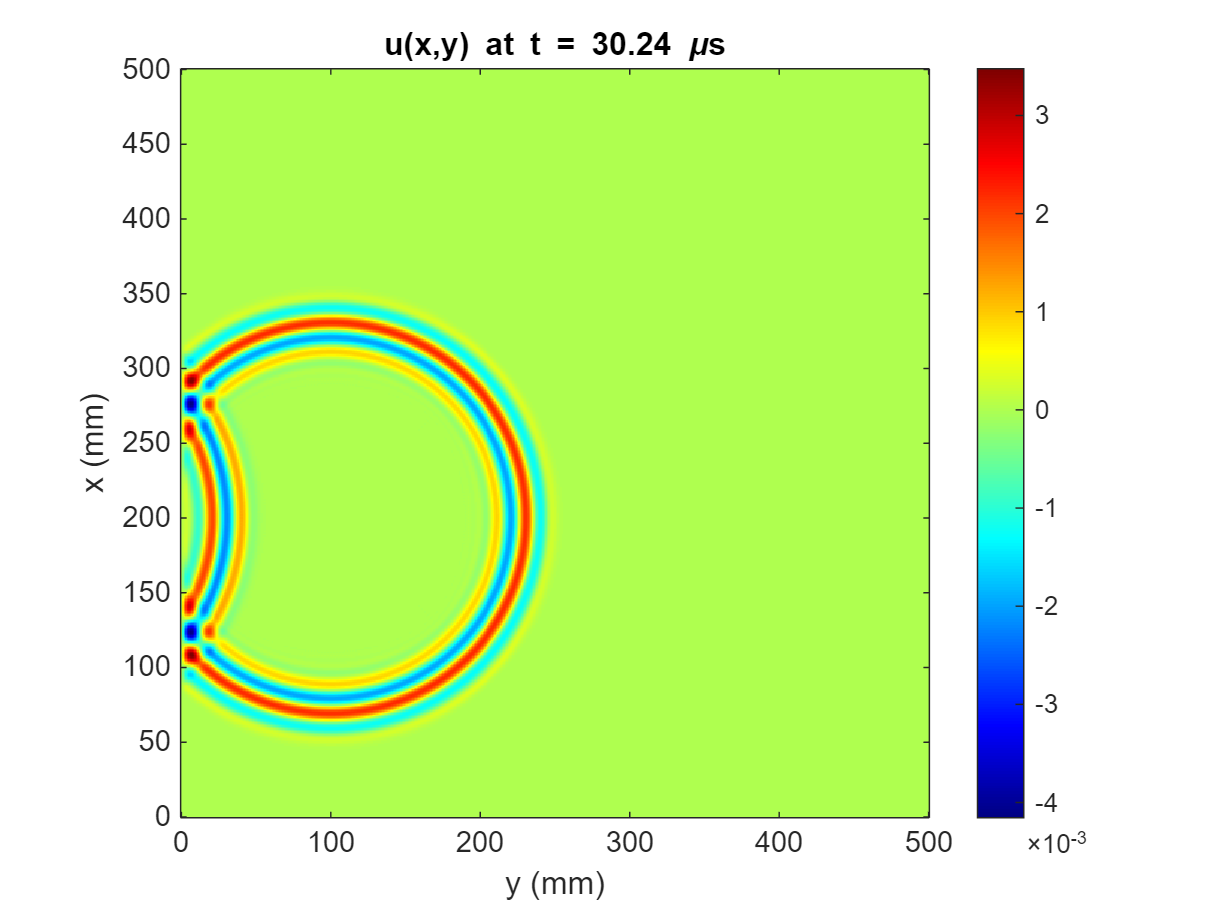

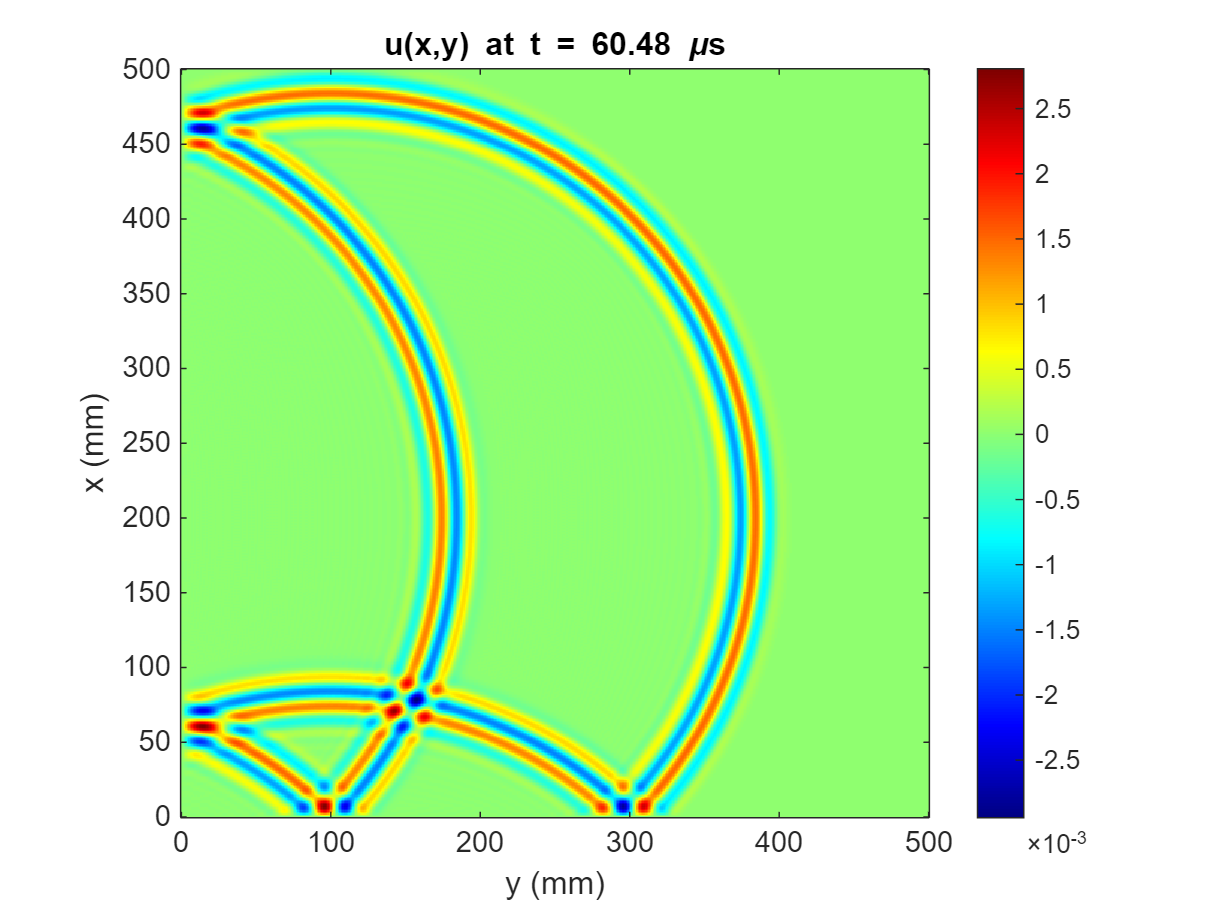

sim2DF(0.2,0.1)

%Run in Command Window for Real-Time animation:
%AnimateTask2F(snap_i,y,x,snaps,t_snaps)

## Task 3:

Aluminum wave speed c0 = 5091.8 m/s
dt = 1.200e-07 s, dx = 1.000e-03 m
Source at x=250.0 mm, y=250.0 mm (i=251, j=251)


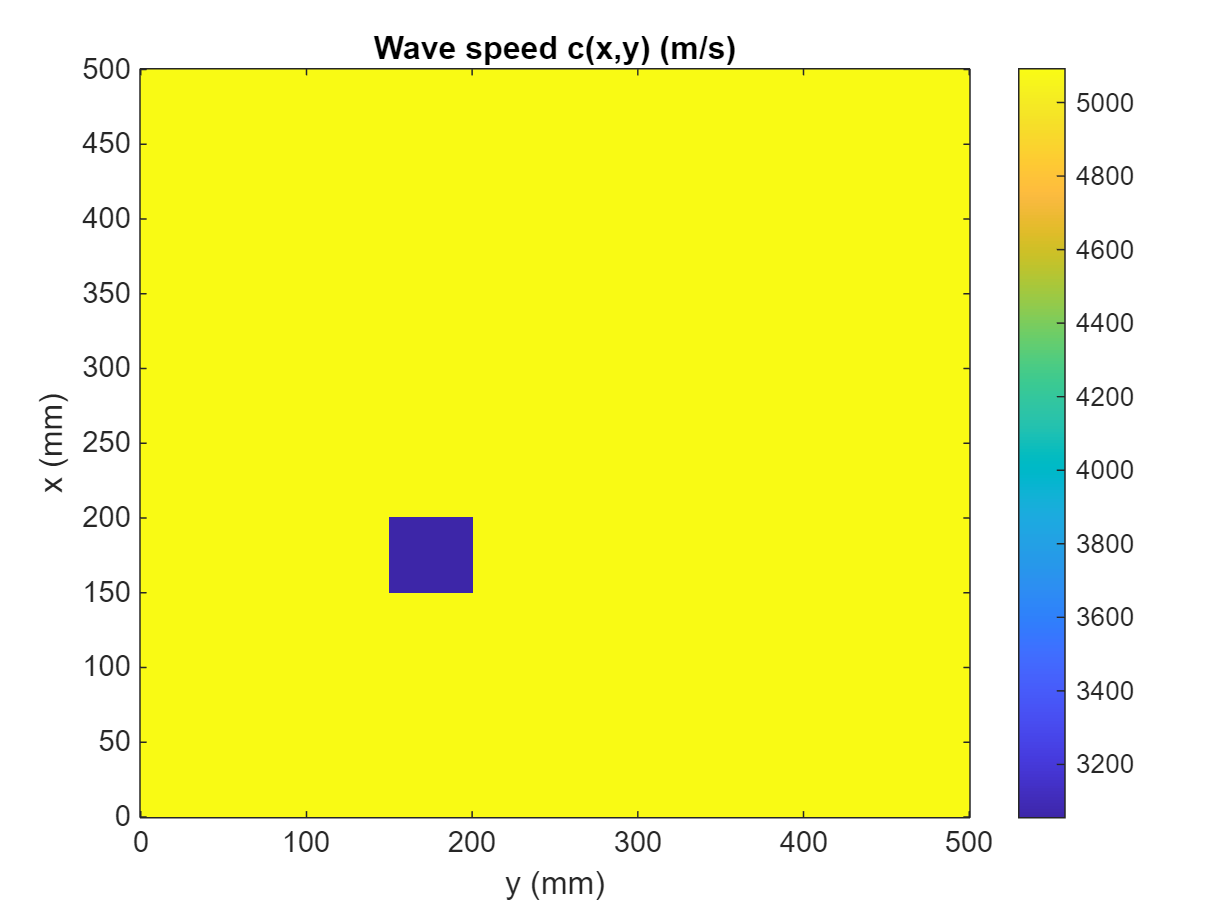

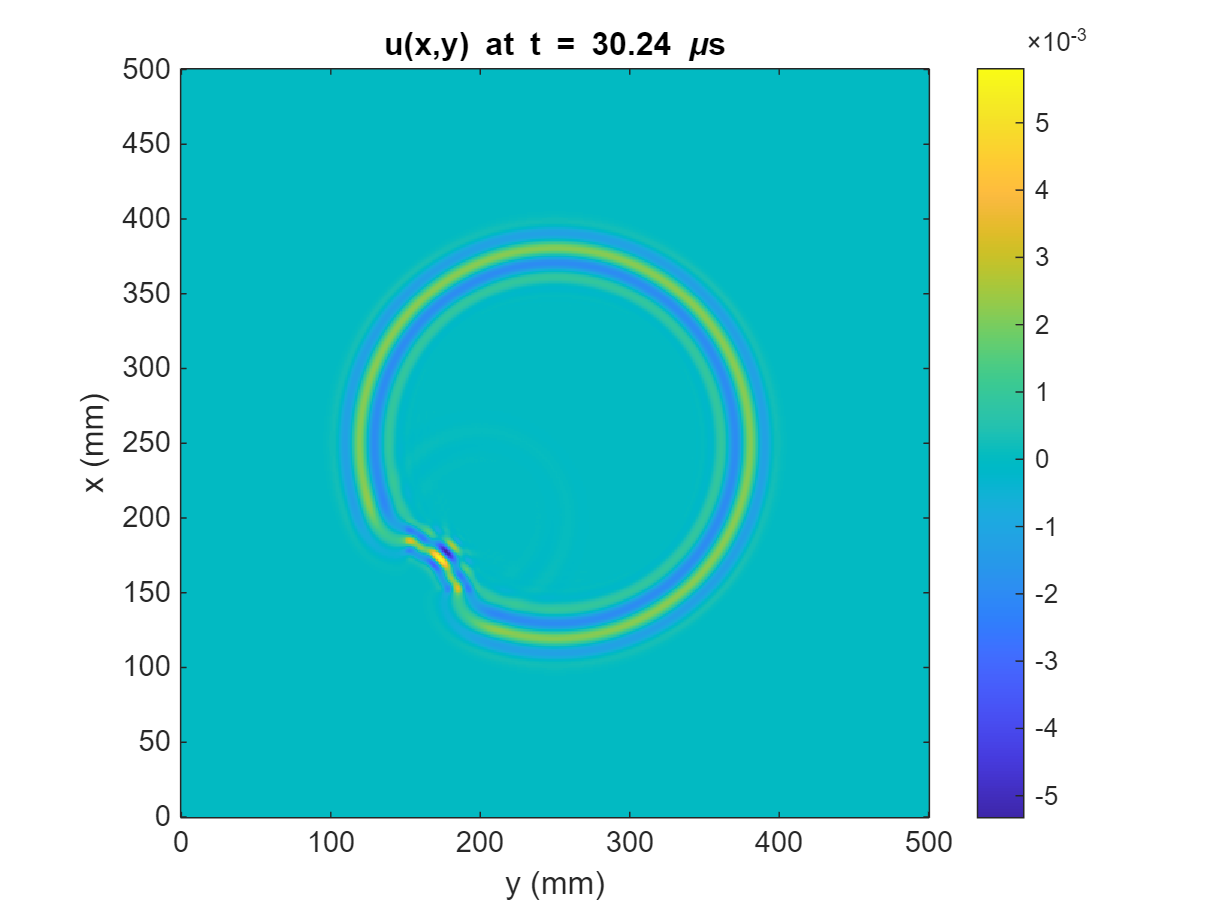

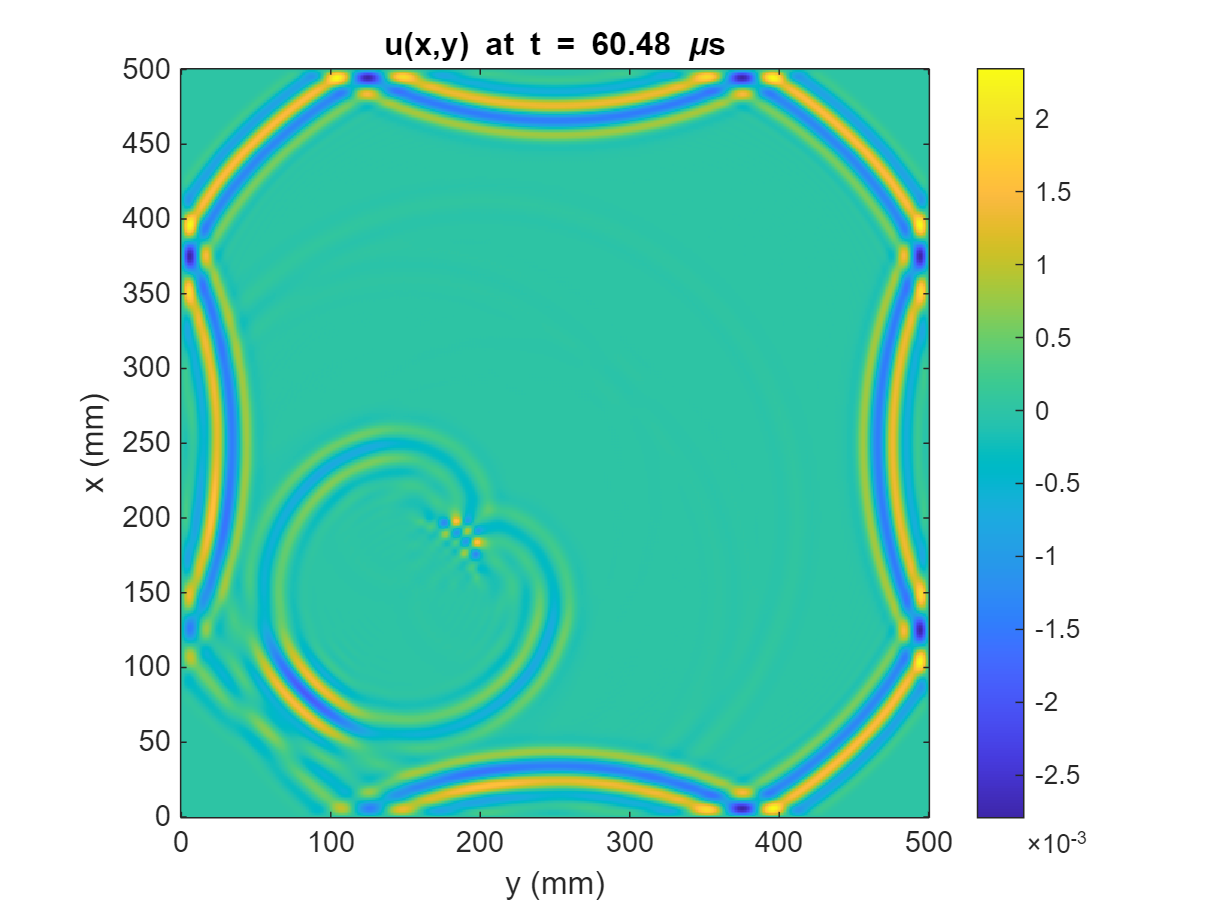

sim2DF_with_discontinuityF(0.25, 0.25)

## Task 4:

% 2D elastic wave (coupled ux, uz) in an aluminum plate

%% ------------------------------------------------------------------------
% 1) Material properties
% -------------------------------------------------------------------------
E  = 70e9;          % Young's modulus [Pa]
rho = 2700;         % density [kg/m^3]
nu  = 0.33;         % Poisson's ratio
mu = E/(2*(1+nu));                      % shear modulus
lambda = (nu*E)/((1+nu)*(1-2*nu));      % Lamé constant
fprintf('Material: Aluminum (E=%.1e Pa, ρ=%.0f kg/m³, ν=%.2f)\n', E, rho, nu);

Material: Aluminum (E=7.0e+10 Pa, ρ=2700 kg/m³, ν=0.33)



%% ------------------------------------------------------------------------
% 2) Discretization parameters
% -------------------------------------------------------------------------
dx = 1e-3;          % spatial step [m]
dz = dx;
dt = 0.12e-6;       % time step [s]
fprintf('dx = %.1e m, dt = %.2e s\n', dx, dt);

dx = 1.0e-03 m, dt = 1.20e-07 s



% Domain
Lx = 0.4;           % 400 mm in x
Lz = 0.4;           % 400 mm in z
x  = 0:dx:Lx; Nx = numel(x);
z  = 0:dz:Lz; Nz = numel(z);

% Time
tmax = 500;         % time steps (like original)
nt = tmax;
fprintf('Grid: %d x %d points, %d time steps\n', Nx, Nz, nt);

Grid: 401 x 401 points, 500 time steps



%% ------------------------------------------------------------------------
% 3) Source: 200 kHz, 2 cycles, Hanning window
% -------------------------------------------------------------------------
f0 = 200e3; ncycles = 2;
Tcycle = 1/f0; Tsrc = ncycles * Tcycle;
t_src = (0:dt:Tsrc);
src_envelope = 0.5 * (1 - cos(2*pi*t_src/Tsrc));
src_signal = sin(2*pi*f0*t_src) .* src_envelope;

%% ------------------------------------------------------------------------
% 4) Source location
% -------------------------------------------------------------------------
xsrc = 0.200; zsrc = 0.200;  % center of plate [m]
[~, isrc] = min(abs(x - xsrc));
[~, jsrc] = min(abs(z - zsrc));
fprintf('Source located at x=%.1f mm, z=%.1f mm (i=%d, j=%d)\n', xsrc*1e3, zsrc*1e3, isrc, jsrc);

Source located at x=200.0 mm, z=200.0 mm (i=201, j=201)



%% ------------------------------------------------------------------------
% 5) Initialize displacement fields
% -------------------------------------------------------------------------
ux_prev = zeros(Nx,Nz);
uz_prev = zeros(Nx,Nz);
ux_curr = zeros(Nx,Nz);
uz_curr = zeros(Nx,Nz);
ux_next = zeros(Nx,Nz);
uz_next = zeros(Nx,Nz);

%% ------------------------------------------------------------------------
% 6) Snapshot setup
% -------------------------------------------------------------------------
Ksnap = max(1, floor(nt/100));
nSnaps = ceil(nt/Ksnap);
snaps_ux = zeros(Nx, Nz, nSnaps);
snaps_uz = zeros(Nx, Nz, nSnaps);
t_snaps  = zeros(nSnaps,1);
snap_i = 1;

%% ------------------------------------------------------------------------
% 7) Time-stepping (explicit FDM for elastic wave equations)
% -------------------------------------------------------------------------
fprintf('Running time-stepping loop...\n');

Running time-stepping loop...


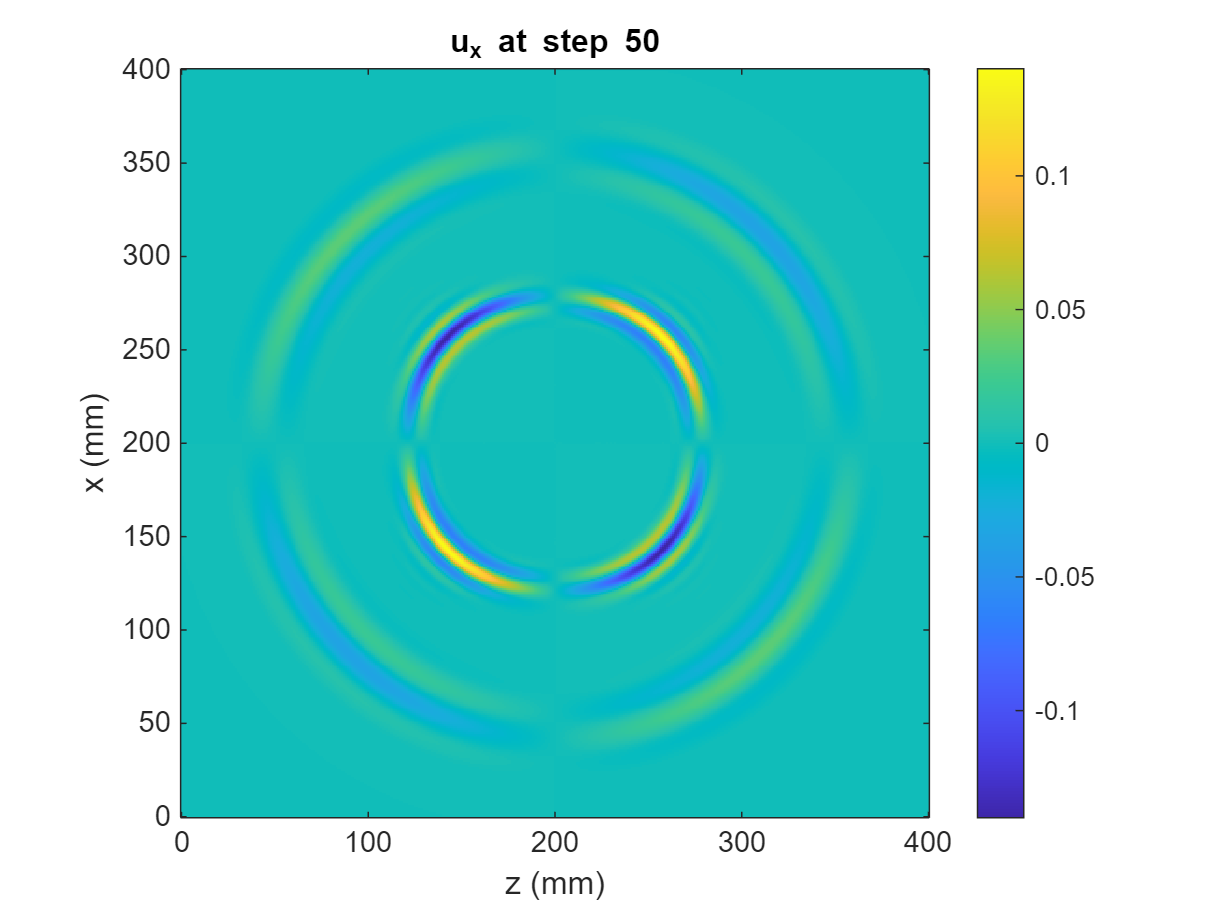

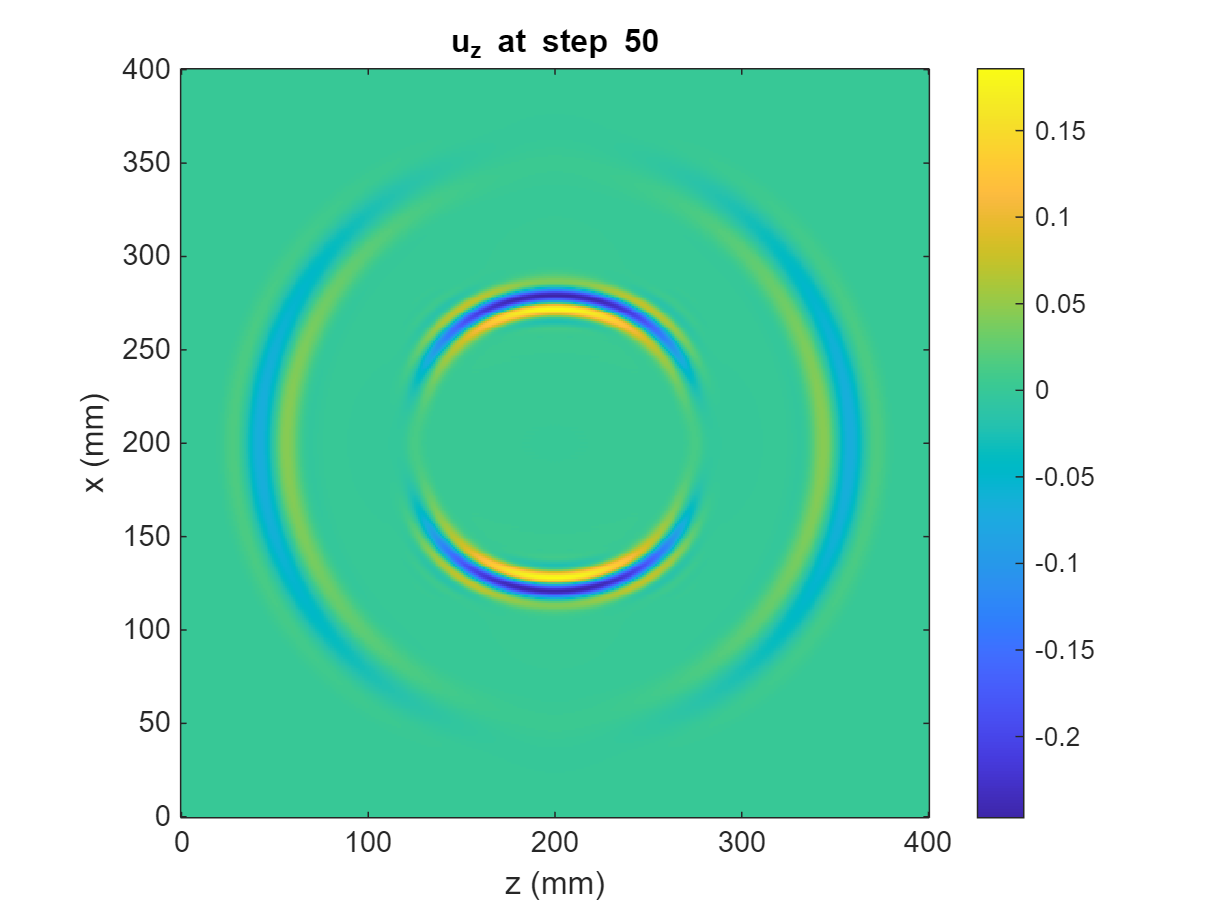

for n = 2:nt-1

    % interior stencil
    for i = 2:Nx-1
        for j = 2:Nz-1
            % 2nd derivatives (central differences)
            Dxx_ux = (ux_curr(i+1,j) - 2*ux_curr(i,j) + ux_curr(i-1,j)) / dx^2;
            Dzz_ux = (ux_curr(i,j+1) - 2*ux_curr(i,j) + ux_curr(i,j-1)) / dz^2;
            Dxx_uz = (uz_curr(i+1,j) - 2*uz_curr(i,j) + uz_curr(i-1,j)) / dx^2;
            Dzz_uz = (uz_curr(i,j+1) - 2*uz_curr(i,j) + uz_curr(i,j-1)) / dz^2;

            % Mixed derivatives
            Dxz_ux = (ux_curr(i+1,j+1) - ux_curr(i+1,j-1) - ux_curr(i-1,j+1) + ux_curr(i-1,j-1)) / (4*dx*dz);
            Dxz_uz = (uz_curr(i+1,j+1) - uz_curr(i+1,j-1) - uz_curr(i-1,j+1) + uz_curr(i-1,j-1)) / (4*dx*dz);

            % Coupled PDEs (Navier equations)
            RHSx = (lambda + 2*mu)*Dxx_ux + mu*Dzz_ux + (lambda + mu)*Dxz_uz;
            RHSz = (lambda + 2*mu)*Dzz_uz + mu*Dxx_uz + (lambda + mu)*Dxz_ux;

            % Time update (central difference in time)
            ux_next(i,j) = 2*ux_curr(i,j) - ux_prev(i,j) + (dt^2/rho)*RHSx;
            uz_next(i,j) = 2*uz_curr(i,j) - uz_prev(i,j) + (dt^2/rho)*RHSz;
        end
    end

    % Source excitation (vertical component)
    if n <= length(src_signal)
        uz_next(isrc, jsrc) = uz_next(isrc, jsrc) + src_signal(n);
    end

    % Boundary conditions: fixed (Dirichlet zero)
    ux_next([1 end],:) = 0; ux_next(:,[1 end]) = 0;
    uz_next([1 end],:) = 0; uz_next(:,[1 end]) = 0;

    % Save snapshots
    if mod(n,Ksnap)==0
        snaps_ux(:,:,snap_i) = ux_next;
        snaps_uz(:,:,snap_i) = uz_next;
        t_snaps(snap_i) = n*dt;
        snap_i = snap_i + 1;
    end

    % Shift time levels
    ux_prev = ux_curr;
    uz_prev = uz_curr;
    ux_curr = ux_next;
    uz_curr = uz_next;
end



%% ------------------------------------------------------------------------
% 8) Static snapshots
% -------------------------------------------------------------------------
t_targets = [50, 200, 400]; % time steps to show
for tt = t_targets
    if tt < snap_i
        figure('Name',sprintf('Snapshot step %d',tt));
        
        imagesc(z*1e3, x*1e3, snaps_ux(:,:,tt));
        title(sprintf('u_x at step %d', tt)); axis equal tight xy; colorbar;
        xlabel('z (mm)'); ylabel('x (mm)');
        
        figure('Name',sprintf('Snapshot step %d',tt));

        imagesc(z*1e3, x*1e3, snaps_uz(:,:,tt));
        title(sprintf('u_z at step %d', tt)); axis equal tight xy; colorbar;
        xlabel('z (mm)'); ylabel('x (mm)');
    end
end

%Run in Command Window for Real-Time animation:
% Task4_real_time_simF(snap_i,z,x,snaps_ux,t_snaps,snaps_uz);

function sim2DF(xsrc,ysrc)

% Task2_FDM_2D_Aluminum_Task1Style.m
% 2D acoustic wave on an aluminum plate
%% 1) Material & discretization (as in Task 1)
E   = 70e9;      % Young's modulus [Pa]
rho = 2700;      % density [kg/m^3]
c   = sqrt(E/rho); 
fprintf('Aluminum wave speed c = %.1f m/s\n', c);

dx = 1e-3;       % spatial step in x [m]
dy = dx;         % spatial step in y [m]
dt = 0.12e-6;    % time step [s]
r2 = (c*dt/dx)^2;
fprintf('CFL = %.4f\n', sqrt(r2));

%% 2) Domain & time
Lx = 0.5;        % plate length in x [m]
Ly = 0.5;        % plate length in y [m]
x  = 0:dx:Lx;    Nx = numel(x);
y  = 0:dy:Ly;    Ny = numel(y);

tmax = 150e-6;   % total simulation time [s]
nt   = ceil(tmax/dt);
time = (0:nt-1)*dt;

%% 3) Source time‐function (200 kHz, 2 cycles, Hanning window)
f0        = 200e3;       
ncycles   = 2;
Tcycle    = 1/f0;
Tsrc      = ncycles*Tcycle;
t_src     = time;
src_envelope = zeros(size(t_src));
idx_src     = (t_src>=0) & (t_src<=Tsrc);
src_envelope(idx_src) = 0.5*(1 - cos(2*pi*t_src(idx_src)/Tsrc));
src_signal = sin(2*pi*f0*t_src) .* src_envelope;

% % plot to check
% figure; plot(t_src*1e6, src_signal);
% xlabel('time (\mus)'); ylabel('src disp (arb)');
% title('2-cycle Hanninged sine (200 kHz)');

% precompute discrete acceleration of source
src_acc = zeros(size(src_signal));
src_acc(2:end-1) = ( src_signal(3:end) - 2*src_signal(2:end-1) + src_signal(1:end-2) )/dt^2;
% edges = 0

%% 4) Source location
% xsrc = 0.25; ysrc = 0.25;
[~, isrc] = min(abs(x - xsrc));
[~, jsrc] = min(abs(y - ysrc));
fprintf('Source at x=%.1f mm, y=%.1f mm (i=%d, j=%d)\n', xsrc*1e3, ysrc*1e3, isrc, jsrc);

%% 5) Initialize fields
u_prev = zeros(Nx,Ny);    % u^{n-1}
u_curr = zeros(Nx,Ny);    % u^{n}
u_next = zeros(Nx,Ny);    % u^{n+1}

% smooth start: impose first displacement at t=0
u_curr(isrc,jsrc) = src_signal(1);
u_prev(isrc,jsrc) = 0;

%% 6) Prepare movie frames
Ksnap   = max(1, floor(nt/100));
nSnaps  = ceil(nt/Ksnap);
snaps   = zeros(Nx,Ny,nSnaps);
t_snaps = zeros(nSnaps,1);
snap_i  = 1;

%% 7) Time-stepping
for n = 1:nt
  % interior 5-point stencil
  u_next(2:end-1,2:end-1) = 2*u_curr(2:end-1,2:end-1) - u_prev(2:end-1,2:end-1) ...
    + r2*( ...
        u_curr(3:end,2:end-1) + u_curr(1:end-2,2:end-1) ...
      + u_curr(2:end-1,3:end) + u_curr(2:end-1,1:end-2) ...
      - 4*u_curr(2:end-1,2:end-1) );
  
  % inject source via exact accel.
  u_next(isrc,jsrc) = u_next(isrc,jsrc) + src_acc(n)*dt^2;
  
  % Dirichlet BC: zero on all edges
  u_next([1 end],:) = 0;
  u_next(:,[1 end]) = 0;
  
  % record snapshot
  if mod(n,Ksnap)==0
    snaps(:,:,snap_i)   = u_next;
    t_snaps(snap_i)     = n*dt;
    snap_i = snap_i + 1;
  end
  
  % shift time levels
  u_prev = u_curr;
  u_curr = u_next;
end

% AnimateTask2F(snap_i,y,x,snaps,t_snaps);
%% 9) Plots

t_target = 30e-6;    
plotLocal(t_target)
t_target = 60e-6;    
plotLocal(t_target)



function plotLocal(t_target)
% find index of snapshot closest to t_target
[~, k30] = min(abs(t_snaps - t_target));

% plot that frame
figure('Name',sprintf('Snapshot at t=%.2f us',t_snaps(k30)*1e6));
imagesc(y*1e3, x*1e3, snaps(:,:,k30));  
axis equal tight xy;
colormap jet; colorbar;
xlabel('y (mm)');  ylabel('x (mm)');
title(sprintf('u(x,y) at t = %.2f \\mus', t_snaps(k30)*1e6));
end
end
function AnimateTask2F(snap_i,y,x,snaps,t_snaps)
%% 8) Animate
figure('Name','2D Wave Propagation','Units','normalized',...
       'Position',[.2 .2 .6 .6]);
for k = 1:snap_i-1
  imagesc(y*1e3, x*1e3, snaps(:,:,k));
  axis equal tight xy;
  colormap jet; colorbar;
  title(sprintf('t = %.2f \\mus', t_snaps(k)*1e6));
  xlabel('y (mm)'); ylabel('x (mm)');
  pause(0.05);
end
end
function sim2DF_with_discontinuityF(xsrc, ysrc)
% sim2DF_with_rectangle_discontinuity.m
% 2D acoustic wave on an aluminum plate with a rectangular discontinuity
% Usage: sim2DF_with_discontinuityF(xsrc, ysrc)
% xsrc, ysrc in meters
clearvars -except xsrc ysrc; clc;

%% 1) Material & discretization (as in Task 1/2)
E   = 70e9;      % Young's modulus [Pa]
rho = 2700;      % density [kg/m^3]
c0  = sqrt(E/rho);          % background wave speed
fprintf('Aluminum wave speed c0 = %.1f m/s\n', c0);

dx = 1e-3;       % spatial step in x [m]
dy = dx;
dt = 0.12e-6;    % time step [s]
fprintf('dt = %.3e s, dx = %.3e m\n', dt, dx);

%% 2) Domain & time
Lx = 0.5; Ly = 0.5;
x  = 0:dx:Lx;    Nx = numel(x);
y  = 0:dy:Ly;    Ny = numel(y);
tmax = 150e-6;
nt = ceil(tmax/dt);
time = (0:nt-1)*dt;

%% 3) Source time‐function (200 kHz, 2 cycles, Hanning window)
f0 = 200e3; ncycles = 2;
Tcycle = 1/f0; Tsrc = ncycles*Tcycle;
t_src = time;
src_envelope = zeros(size(t_src));
idx_src = (t_src>=0) & (t_src<=Tsrc);
src_envelope(idx_src) = 0.5*(1 - cos(2*pi*t_src(idx_src)/Tsrc));
src_signal = sin(2*pi*f0*t_src) .* src_envelope;

% discrete acceleration for exact forcing injection
src_acc = zeros(size(src_signal));
src_acc(2:end-1) = ( src_signal(3:end) - 2*src_signal(2:end-1) + src_signal(1:end-2) )/dt^2;

%% 4) Source location -> grid indices
[~, isrc] = min(abs(x - xsrc));
[~, jsrc] = min(abs(y - ysrc));
fprintf('Source at x=%.1f mm, y=%.1f mm (i=%d, j=%d)\n', xsrc*1e3, ysrc*1e3, isrc, jsrc);

%% 5) Build spatially varying c(x,y) with a rectangular discontinuity
% rectangle bounds (in meters). Interpreted from your suggestion: 150-200 mm
rect_x = [0.150, 0.200];
rect_y = [0.150, 0.200];

% baseline c^2 field
c_field = c0 * ones(Nx,Ny);

% choose a contrasting wave speed inside the rectangle (e.g. slower inclusion)
c_rect_factor = 0.6;        % rectangle speed = 0.6 * c0 (you can change this)
ix_rect = find(x >= rect_x(1) & x <= rect_x(2));
jy_rect = find(y >= rect_y(1) & y <= rect_y(2));
c_field(ix_rect, jy_rect) = c0 * c_rect_factor;

% store c^2 for use in the discretization (we use c^2)
c2 = c_field.^2;

%% 6) Initialize fields
u_prev = zeros(Nx,Ny);
u_curr = zeros(Nx,Ny);
u_next = zeros(Nx,Ny);

% smooth start: impose first displacement at t=0 at source
u_curr(isrc,jsrc) = src_signal(1);
u_prev(isrc,jsrc) = 0;

%% 7) Prepare snapshots / visualization
Ksnap = max(1, floor(nt/100));      % how often to save frames
nSnaps = ceil(nt / Ksnap);
snaps = zeros(Nx,Ny,nSnaps);
t_snaps = zeros(nSnaps,1);
snap_i = 1;

%% 8) Main time-stepping
% We discretize u_tt = div(c^2 * grad u) using half-cell averaging of c^2
for n = 1:nt
    % interior loop (2..Nx-1, 2..Ny-1)
    for i = 2:Nx-1
        for j = 2:Ny-1
            % half-cell (interface) c^2 averages
            c2_ip = 0.5*(c2(i,j)   + c2(i+1,j)); % i+1/2
            c2_im = 0.5*(c2(i,j)   + c2(i-1,j)); % i-1/2
            c2_jp = 0.5*(c2(i,j)   + c2(i,j+1)); % j+1/2
            c2_jm = 0.5*(c2(i,j)   + c2(i,j-1)); % j-1/2

            % divergence form discretization
            term_x = ( c2_ip*(u_curr(i+1,j) - u_curr(i,j)) - c2_im*(u_curr(i,j) - u_curr(i-1,j)) ) / dx^2;
            term_y = ( c2_jp*(u_curr(i,j+1) - u_curr(i,j)) - c2_jm*(u_curr(i,j) - u_curr(i,j-1)) ) / dy^2;
            lap_div = term_x + term_y;

            % time update (central in time)
            u_next(i,j) = 2*u_curr(i,j) - u_prev(i,j) + dt^2 * lap_div;
        end
    end

    % inject source via exact discrete acceleration
    u_next(isrc, jsrc) = u_next(isrc, jsrc) + src_acc(n) * dt^2;

    % Dirichlet BC: zero at all edges
    u_next([1 end], :) = 0;
    u_next(:, [1 end]) = 0;

    % save snapshot
    if mod(n, Ksnap) == 0
        snaps(:,:,snap_i) = u_next;
        t_snaps(snap_i)   = n*dt;
        snap_i = snap_i + 1;
    end

    % shift in time
    u_prev = u_curr;
    u_curr = u_next;
end

%% 9) Plots: show a few snapshots and a map of c(x,y)
figure('Name','c(x,y) map'); imagesc(y*1e3, x*1e3, c_field); axis xy; colorbar;
xlabel('y (mm)'); ylabel('x (mm)'); title('Wave speed c(x,y) (m/s)');

% show snapshots at two target times (choose times inside recorded snaps)
t_targets = [30e-6, 60e-6];
for k = 1:numel(t_targets)
    [~, idx_k] = min(abs(t_snaps - t_targets(k)));
    figure('Name',sprintf('Snapshot t=%.2f us', t_snaps(idx_k)*1e6));
    imagesc(y*1e3, x*1e3, snaps(:,:,idx_k));
    axis equal tight xy;
    colorbar;
    xlabel('y (mm)'); ylabel('x (mm)');
    title(sprintf('u(x,y) at t = %.2f \\mus', t_snaps(idx_k)*1e6));
end

% Optional: animate small sequence (uncomment if you want)
% figure('Name','Animation'); for k=1:(snap_i-1); imagesc(y*1e3,x*1e3,snaps(:,:,k)); axis equal tight xy; colorbar; title(sprintf('t=%.2f us',t_snaps(k)*1e6)); pause(0.03); end

end
function Task4_real_time_simF(snap_i,z,x,snaps_ux,t_snaps,snaps_uz)
%% Task4_real_time_simF(snap_i,z,x,snaps_ux,t_snaps,snaps_uz);
% Visualization
% -------------------------------------------------------------------------
% Choose whether to animate ux or uz
anim_type = 'uz';  % options: 'ux' or 'uz'

figure('Name','2D Elastic Wave Animation','Units','normalized','Position',[0.1 0.1 0.7 0.7]);
for k = 1:snap_i-1
    if strcmp(anim_type,'ux')
        imagesc(z*1e3, x*1e3, snaps_ux(:,:,k));
        title(sprintf('u_x(x,z), t = %.2f \\mus', t_snaps(k)*1e6));
    else
        imagesc(z*1e3, x*1e3, snaps_uz(:,:,k));
        title(sprintf('u_z(x,z), t = %.2f \\mus', t_snaps(k)*1e6));
    end
    axis equal tight xy;
    xlabel('z (mm)'); ylabel('x (mm)');
    colorbar;
    clim([-0.05 0.05]);
    pause(0.05);
end
end